# Task 2  

# Joint trajectory

###  q(t) from q(0) = (0,0,0) to q(2) = (2,3,4) 

"with null initial and final velocities and accelerations"

type =  (polynomial)

% polynomial
t0 = 0;
tf = 2;
% first joint  at (0,0,0)
q0 = [0 0 0]

q0 =      0     0     0


% final joint  at (2,3,4)
qf = [2 3 4]

qf =      2     3     4


% first velocity and acceleration
q0_dot = [0 0 0];
a0 = [0 0 0];
% final velocity and acceleration
qf_dot = [0 0 0];
af = [0 0 0];

POINTS= 100 % ASSUME THERE ARE ONE HUNDRED POINTS THAT THE ROBOT WILL PASS BY 

POINTS = 100

 pos = zeros(POINTS,3);
 vel = zeros(POINTS,3);
 acc = zeros(POINTS,3);
A = [1 t0 t0^2 t0^3 t0^4 t0^5;
     0 1 2*t0 3*t0^2 4*t0^3 5*t0^4;
     0 0 2 6*t0 12*t0^2 20*t0^3;
     1 tf tf^2 tf^3 tf^4 tf^5;
     0 1 2*tf 3*tf^2 4*tf^3 5*tf^4;
     0 0 2 6*tf 12*tf^2 20*tf^3]

A =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     2     0     0     0
     1     2     4     8    16    32
     0     1     4    12    32    80
     0     0     2    12    48   160


 for JOINTS = 1:3
     b = [q0(JOINTS) q0_dot(JOINTS) a0(JOINTS) qf(JOINTS) qf_dot(JOINTS) af(JOINTS)]';
     %  inv(A) * b
     x =A\b;
     t = linspace(t0,tf,POINTS);%assign the results to the coeffs
      pos(:,JOINTS) = x(1)+x(2).*t + x(3).*t.^2 + x(4).* t.^3+ x(5).*t.^4 + x(6).*t.^5;
      vel(:,JOINTS) = x(2) + 2*x(3).*t + 3*x(4).* t.^2+ 4*x(5).*t.^3 + 5*x(6).*t.^4;
      acc(:,JOINTS) = 2*x(3)+ x(4)*6.*t + x(5)*12.*t.^2 + x(6)* 20.*t.^3;
 end

## Plotting of the joint angles, velocities, acceleration

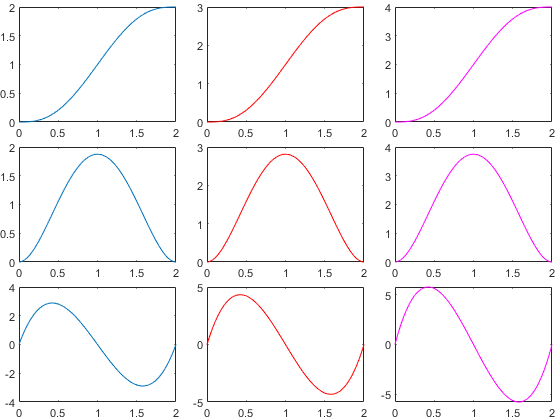

plt_1 = tiledlayout(3,3); % Requires R2019b or later
nexttile
plot(t,pos(:,1),'DisplayName','q1_pos')
nexttile
plot(t,pos(:,2),'r','DisplayName','q2_pos')
nexttile
plot(t,pos(:,3),'m','DisplayName','q3_pos')
nexttile
plot(t,vel(:,1),'DisplayName','q1_vel')
nexttile
plot(t,vel(:,2),'r','DisplayName','q2_vel')
nexttile
plot(t,vel(:,3),'m','DisplayName','q3_vel')
nexttile
plot(t,acc(:,1),'DisplayName','q1_acc')
nexttile
plot(t,acc(:,2),'r','DisplayName','q2_acc')
nexttile
plot(t,acc(:,3),'m','DisplayName','q3_acc')
plt_1.Padding = 'none';
plt_1.TileSpacing = 'none'; 